clearvars

files = dir('*tif');
n_files = numel(files);
disp(['There are ',num2str(n_files),' files'])

There are 3 files


%Variable Preamble
emg = 0; % Enter the EM Gain value used on the camera
pix2pho = em_gain(emg);    %Pixel to photon ratio
q = 0.122;          % Pixel size in um
pixw = 6;       % radius to localize (final image size is (2*pixw+1)^2 pixels)
an_dir = 'Analysis'; % name of analysis directory
angle = 0; %approximate astig rotation in degrees
sv_im = 'n'; % set to y/Y to save image of localizations
framechunk_drift_correct = 1000;
thresh = 5;
comp_name = get_computer_name();
load([comp_name , '\Documents\GitHub\Matlab-Master\2-Channel Codes\2_color_calibration.mat']);
load([comp_name , '\Documents\GitHub\Matlab-Master\2-Channel Codes\2_color_calibration.mat'], 'split');
load([comp_name , '\Documents\GitHub\Matlab-Master\Hurricane\hurricane_functions\z_calib.mat']);
try
load('C:\Users\ajnel\Documents\GitHub\Matlab-Master\Hurricane\Tolfile.mat');
catch
    load('C:\Users\AJN Lab\Documents\GitHub\Matlab-Master\Hurricane\Tolfile.mat');
end

% File Loading
file = 1;
i1 = readtiff(files(file).name);

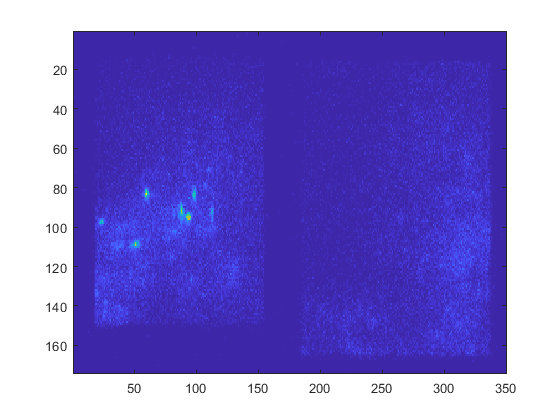

frame = 31;
imagesc(i1(:,:,frame));

[m,n,o] = size(i1);
iprod = gpu_rball(i1);

% Wavelet deniosing for identification
iwaves = gpu_waves(iprod);

Wavelet: Conv step 1 done
Wavelet: Conv step 2 done


se = strel('Disk',1);
ifind = imerode(iwaves,se);
frame = 307

frame = 307

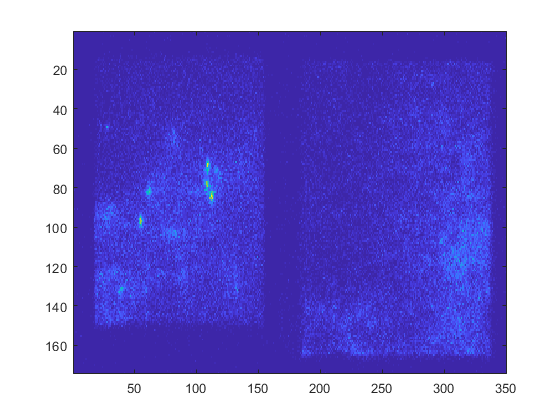

imagesc(iprod(:,:,frame));

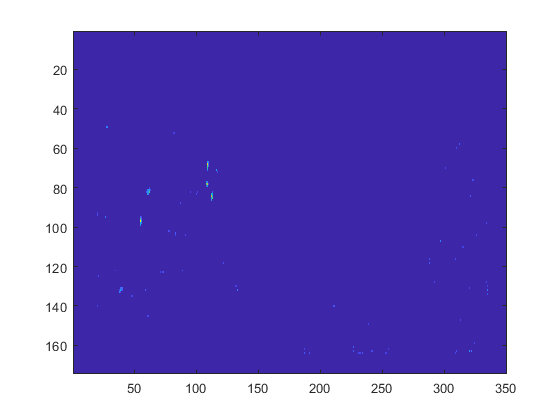

imagesc(ifind(:,:,frame))

% Skipping blocking
%Identification
thresh = 3

thresh = 3

dps = cpu_peaks(ifind,thresh,pixw);

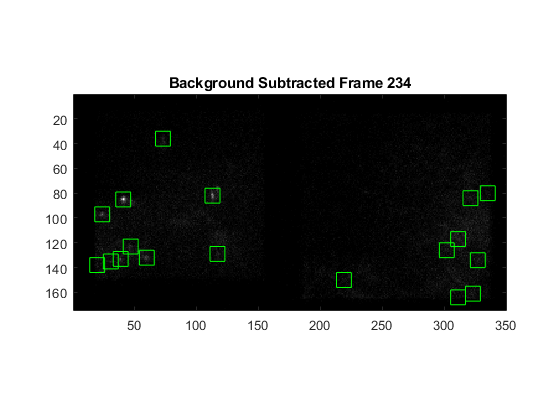

% in_d_eye(iprod, dps, pixw);

clear ip ipf i1

% divide up the data
[iloc, fnum, cents] = divide_up(iprod, pixw, dps);
[m,n,o] = size(iloc);
% remove duplicate data
[ind] = find_fm_dupes(cents,fnum,pixw*1.5);
iloc(:,:,ind) = [];
cents(ind,:) = [];
fnum(ind) = [];
cal.q = q;

split = 171; % fill in this value based off data
id = cents(:,1) < split; % red localization
cdata = fit_channel_data(iloc(:,:,id), fnum(id), cents(id,:), cal, 'red');

Of the values entered, 0% were rejected


id = logical(1-id);
cdata = fit_channel_data(iloc(:,:,id), fnum(id), cents(id,:), cal, 'orange', cdata);

Of the values entered, 0% were rejected


cdata_raw = cdata; % Store raw cdata to track localization losses

scatter3(cdata.red.xf,cdata.red.yf,cdata.red.zf/2.5,5,'filled')
hold on
% scatter3(cdata.orange.xf,cdata.orange.yf,cdata.orange.zf/2.5,5,'filled')
hold off
colormap('jet')
axis equal
title('Cdata Raw')
max(cal.red.z0s)

ans = 2.9500

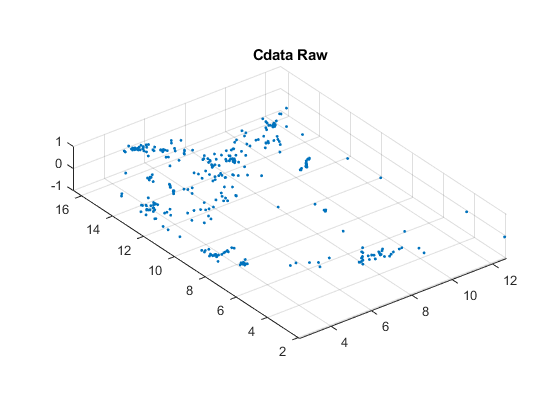

zlim([-1 1])

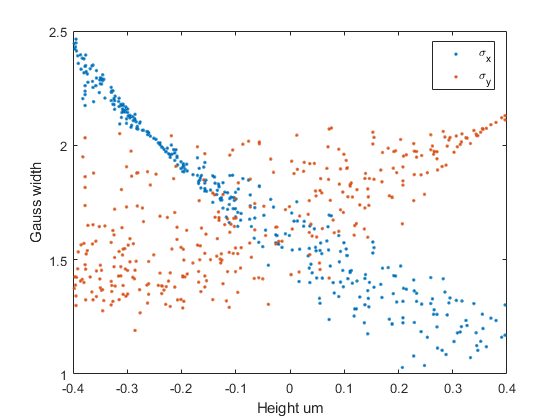

plot(cdata.red.zf,cdata.red.fits(:,4),'.')
hold on
plot(cdata.red.zf,cdata.red.fits(:,5),'.')
hold off
xlabel('Height um')
ylabel('Gauss width')
legend('\sigma_x','\sigma_y','Location','best')

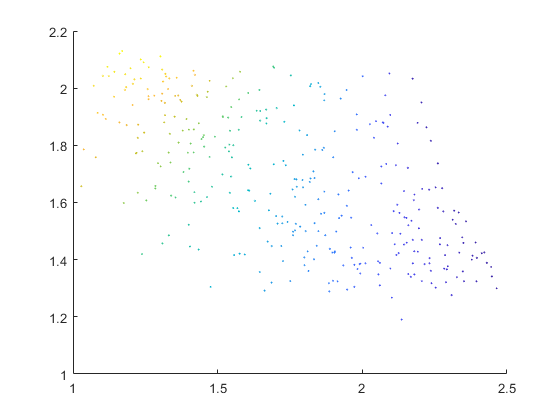

figure
scatter(cdata.red.fits(:,4),cdata.red.fits(:,5),3,cdata.red.zf,'filled')

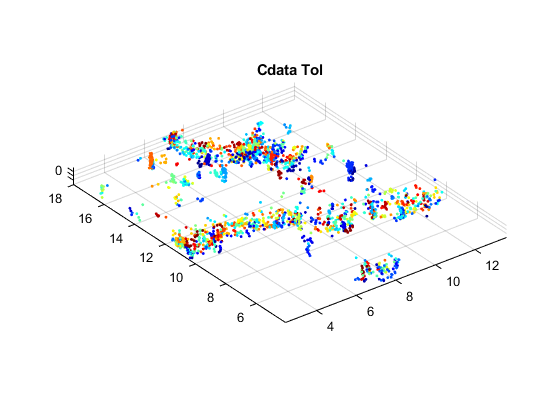


tol.q = q;
cdata_tol = apply_tolerance_to_cdata(cdata, tol, 'red');
% cdata_tol = apply_tolerance_to_cdata(cdata_tol, tol, 'orange');
scatter3(cdata_tol.red.xf,cdata_tol.red.yf,cdata_tol.red.zf,5,cdata_tol.red.framenumber,'filled')
% hold on
% scatter3(cdata.orange.xf,cdata.orange.yf,cdata.orange.zf,5,cdata.orange.framenumber,'filled')
% hold off
colormap('jet')
axis equal
title('Cdata Tol')

% Massive loss of 'good' molecules at tolerance, skipping onto cluster
% clean
disp(num2str(numel(cdata_tol.red.xf) ))

2429


disp(num2str(numel(cdata.red.xf) ))

38721


remove_id = cdata.red.xf <3.2 | cdata.red.yf<4 | cdata.red.xf > 18;


cdata = remove_cdata(cdata,'red',remove_id);
% cdata = remove_cdata(cdata,'orange',remove_id(colors == 2));

cdata_cc = cluster_clean(cdata,0.2, 10);
scatter3(cdata_cc.red.xf,cdata_cc.red.yf,cdata_cc.red.zf,5,cdata_cc.red.framenumber,'filled')
hold on
scatter3(cdata_cc.orange.xf,cdata_cc.orange.yf,cdata_cc.orange.zf,5,cdata_cc.orange.framenumber,'filled')
hold off
colormap('jet')
axis equal
title('Cdata CC')

cdata_fin = model_drift_correction(cdata_tol,'Red',1000); 

Reference to non-existent field 'orange'.

Error in model_drift_correction (line 8)
[xfo, yfo] = make_nn_channel_transform(cdata.orange.xf,cdata.orange.yf);

scatter(cdata_fin.red.xf-mean(cdata_fin.red.xf),cdata_fin.red.yf-mean(cdata_fin.red.yf),2,'filled')
hold on
scatter(cdata_fin.orange.xf,cdata_fin.orange.yf,3,'filled')
hold off
% colormap('jet')
axis equal
title('Cdata fin')

[xfo, yfo] = make_nn_channel_transform(cdata.orange.xf,cdata.orange.yf);
zfo = -cdata.orange.zf;
xfr = cdata.red.xf;
yfr = cdata.red.yf;
zfr = -cdata.red.zf;
xfo = xfo-mean(xfr);
zfo = zfo-mean(zfr);
yfo = yfo-mean(yfr);
xfr = xfr-mean(xfr);
zfr = zfr-mean(zfr);
yfr = yfr-mean(yfr);
frame_r = cdata.red.framenumber;
frame_o = cdata.orange.framenumber;
next_color = 'orange';
% Make data arrays
r_data = [xfr, yfr, zfr];
o_data = [xfo, yfo, zfo];
frames_in_chunk = 2000;
% Build t0 model by segmenting out early data
index = frame_r >= 2000 & frame_r < 2000+frames_in_chunk;
data0 = r_data(index,:);
frame0 = frame_r(index);
epsb = 0.2;
epsn = 0.006;
amax = 50;
lamb = 100;
alpha = 0.5;
decr = 0.995;
vangle = [00, 90];
params = [epsb, epsn, amax, lamb, alpha, decr];

% [w, T, A] = func_gng(data0, params);
w0 = w;
% Reduce w0 down to a decreased number of nodes
% Every decrease, replace existing nodes using a k-means / radius
radius = 0.1; % micron radius for consideration
seen = w0(:,1)*0; % index variable to record whether a node has been removed
w1 = [];

scatter3(data0(:,1), data0(:,2), data0(:,3), 3, data0(:,3),'filled')
index = data0(:,1)  < 0.15 & data0(:,1) >-0.164 & data0(:,2) < -2.97;
x = frame0(index);
y = data0(index,3);

plot(x,y)

dz = spline(x, gausssmooth(y,5,10),frame0);
scatter3(data0(:,1), data0(:,2), data0(:,3)- dz, 3, data0(:,3),'filled')